# **Résultats simulation Monte-Carlo intercalibrage**

## **Données d'intercalibrage**

- **Instrument de référence**

disp([ref_cast.uvp])

uvp5-sn002


- **Nom du profil**

disp([ref_base.profilename])

    {'sum_int_ac_int_bb_int_b_ba_int_b_ca_int_b_da_cast_xc'}



- **Instrument à ajuster**

disp([adj_cast.uvp])

uvp6-sn000008LP


- **Nom du profil**

disp([adj_base.profilename])

    {'sum_020_sample_38_020_sample_84_020_sample_104_020_sample_124_020_sample_144_020_sample_184'}



- **Rapport d'intercalibrage d'UVPdb correspondant **

disp(['uvp_calibration_report_of_000008lp_from_sn002_20200221.pdf'])

uvp_calibration_report_of_000008lp_from_sn002_20200221.pdf


## **Résultats Aa**

q_alpha = 1.96;

% Analyse statistique Aa
moy_Aa = mean(aa_adj);
med_Aa = median(aa_adj);
s_Aa = std(aa_adj);

I_Aa = [moy_Aa - q_alpha * s_Aa ; moy_Aa + q_alpha * s_Aa ] ; 
I_Aa_bis = [quantile(aa_adj, 0.025) ; quantile(aa_adj, 0.975)];


 
disp(['------------------------ Résultats Monte-Carlo ------------------------'])

------------------------ Résultats Monte-Carlo ------------------------


disp(['Valeur moyenne                   : ', num2str(moy_Aa)])

Valeur moyenne                   : 0.0025944


disp(['Intervalle de confiance à 95%    : [', num2str(I_Aa(1)) ,' ; ',num2str(I_Aa(2)) ']'])

Intervalle de confiance à 95%    : [0.00025953 ; 0.0049292]


disp(['Valeur médiane                   : ', num2str(med_Aa)])

Valeur médiane                   : 0.0024166


disp(['Intervalle interquantile à 95%   : [', num2str(I_Aa_bis(1)) ,' ; ',num2str(I_Aa_bis(2)) ']'])

Intervalle interquantile à 95%   : [0.00082233 ; 0.0053874]


disp(['Mode                             : ', num2str(mode(round(aa_adj,6)))])

Mode                             : 0.002313



disp(['------------------------ Résultat intercalibrage ------------------------'])

------------------------ Résultat intercalibrage ------------------------


% valeur de Aa du rapport d'intercalibrage
Aa_intercalibrage = 0.002368 ;
disp(['Valeur Aa_adj intercalibrage      : ', num2str(Aa_intercalibrage)])

Valeur Aa_adj intercalibrage      : 0.002368


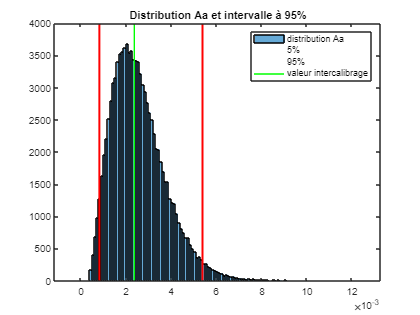


% histogramme de fréquence pour Aa 
figure(1);
histogram(aa_adj);
title('Distribution Aa et intervalle à 95%')
hold on;
line([I_Aa_bis(1), I_Aa_bis(1)], ylim, 'LineWidth', 2, 'Color', 'r');
line([I_Aa_bis(2), I_Aa_bis(2)], ylim, 'LineWidth', 2, 'Color', 'r');
line([Aa_intercalibrage, Aa_intercalibrage], ylim, 'LineWidth', 1, 'Color', 'g') 
legend('distribution Aa', '5%','95%', 'valeur intercalibrage');
hold off;

## Résultats exp

% valeur de exp du rapport d'intercalibrage
exp_intercalibrage = 1.1349 ;

% Analyse statistique expo
moy_expo = mean(expo_adj);
med_expo = median(expo_adj);
s_expo = std(expo_adj);

I_exp = [moy_expo - q_alpha * s_expo ; moy_expo + q_alpha * s_expo ] ; 
I_exp_bis = [quantile(expo_adj,0.025) ; quantile(expo_adj,0.975)] ;


disp(['------------------------ Résultats Monte-Carlo ------------------------'])

------------------------ Résultats Monte-Carlo ------------------------


disp(['Valeur moyenne                   : ', num2str(moy_expo)])

Valeur moyenne                   : 1.1407


disp(['Intervalle de confiance à 95%    : [', num2str(I_exp(1)) ,' ; ',num2str(I_exp(2)) ']'])

Intervalle de confiance à 95%    : [1.022 ; 1.2593]


disp(['Valeur médiane                   : ', num2str(med_expo)])

Valeur médiane                   : 1.136


disp(['Mode                             : ', num2str(mode(round(expo_adj,4)))])

Mode                             : 1.1298



disp(['Intervalle interquantile à 95%   : [', num2str(I_exp_bis(1)) ,' ; ',num2str(I_exp_bis(2)) ']'])

Intervalle interquantile à 95%   : [1.0345 ; 1.2723]


disp(['------------------------ Résultat intercalibrage ------------------------'])

------------------------ Résultat intercalibrage ------------------------


disp(['Valeur exp_adj intercalibrage      : ', num2str(exp_intercalibrage)])

Valeur exp_adj intercalibrage      : 1.1349


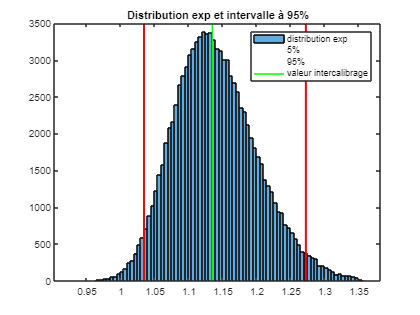


% histogramme de fréquence pour exp 
figure(2);
histogram(expo_adj);
title('Distribution exp et intervalle à 95%')
hold on;
line([I_exp_bis(1), I_exp_bis(1)], ylim, 'LineWidth', 2, 'Color', 'r');
line([I_exp_bis(2), I_exp_bis(2)], ylim, 'LineWidth', 2, 'Color', 'r');
line([exp_intercalibrage, exp_intercalibrage], ylim, 'LineWidth', 1, 'Color', 'g'); % valeur de exp du rapport d'intercalibrage
legend('distribution exp', '5%','95%','valeur intercalibrage','Location','northeast')

## Résultats score


% Analyse statistique score
moy_score = mean(score);
med_score = median(score);
s_score = std(score);

I_score = [moy_score - q_alpha * s_score ; moy_score + q_alpha * s_score ] ; 
I_score_bis = [quantile(score,0.025) ; quantile(score,0.975)] ;

disp(['------------------------ Résultats Monte-Carlo ------------------------'])

------------------------ Résultats Monte-Carlo ------------------------


disp(['Valeur moyenne                  : ', num2str(moy_score)])

Valeur moyenne                  : 0.00116


disp(['Intervalle de confiance à 95%   : [', num2str(I_score(1)) ,' ; ',num2str(I_score(2)) ']'])

Intervalle de confiance à 95%   : [0.00116 ; 0.00116]


disp(['Valeur médiane                  : ', num2str(med_score)])

Valeur médiane                  : 0.00116


disp(['Intervalle interquantile à 95%  : [', num2str(I_score_bis(1)) ,' ; ',num2str(I_score_bis(2)) ']'])

Intervalle interquantile à 95%  : [0.00116 ; 0.00116]


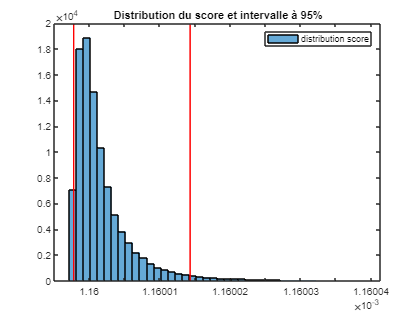

% histogramme des scores
figure(3);
edges = [0.001159997184605:0.000000001:0.00116004];
histogram(score,edges);
title('Distribution du score et intervalle à 95%')
hold on;
line([I_score_bis(1), I_score_bis(1)], ylim, 'LineWidth', 0.5, 'Color', 'r');
line([I_score_bis(2), I_score_bis(2)], ylim, 'LineWidth', 0.5, 'Color', 'r');
legend('distribution score')